# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');

simul.select1 = 1;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stair_gain = 1;   % takes values in {-1, 1}
simul.ramp_gain = 1;    % takes values in [0,1]
simul.stepdeg = 0;      % sets the step amplitude of the deg step
simul.antiWindUp = 1;   % takes values in {-1, 1} -1 anti-windup loop deactivated 1 activated

warning('off','all')

### **[2.1] ANTI-WINDUP**

simul.select1 = 1;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stepdeg = 360;


awu.a = 0.1;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;

anti_windup_step = sim('lab1_anti_windup','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_anti_windup/PID/FIX  (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)


save('anti_windup_step.mat','anti_windup_step');

% deactivatin anti windup and redoing the simulation

awu.Kw = 0;        % Disable Anti windup

no_anti_windup_step = sim('lab1_anti_windup','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_anti_windup/PID/FIX  (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)


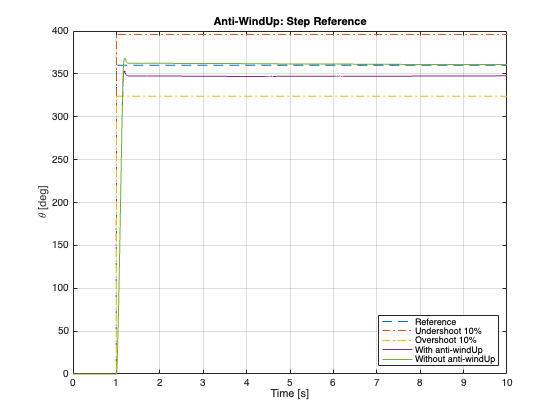

save('no_anti_windup_step.mat','no_anti_windup_step');

%plotting compared results
figure

plot(anti_windup_step.thref.time, anti_windup_step.thref.signals.values,'--');
hold on;
plot(anti_windup_step.thref.time, anti_windup_step.thref.signals.values*1.10,'-.');
plot(anti_windup_step.thref.time, anti_windup_step.thref.signals.values*0.9,'-.');
plot(anti_windup_step.thl_meas.time, anti_windup_step.thl_meas.signals.values);
hold on;
plot(no_anti_windup_step.thl_meas.time, no_anti_windup_step.thl_meas.signals.values);
grid on;
legend('Reference','Undershoot 10%','Overshoot 10%','With anti-windUp', 'Without anti-windUp','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Anti-WindUp: Step Reference');

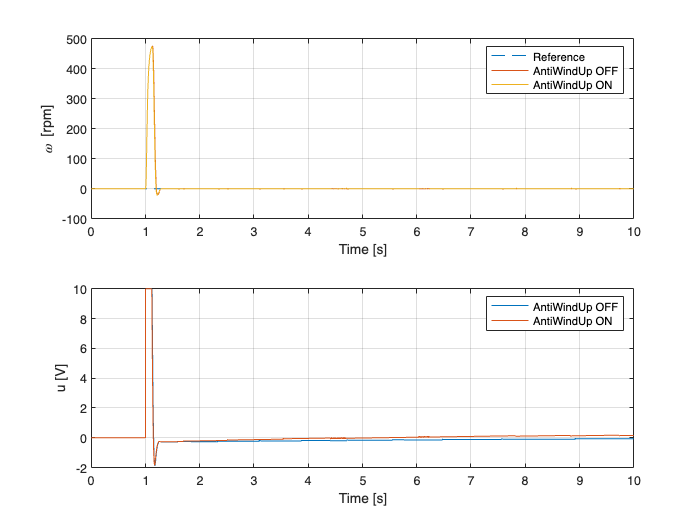

figure
subplot(2,1,1);
plot(no_anti_windup_step.wref.time, no_anti_windup_step.wref.signals.values,'--');
hold on;
plot(no_anti_windup_step.wl_meas.time, no_anti_windup_step.wl_meas.signals.values);
plot(anti_windup_step.wl_meas.time, anti_windup_step.wl_meas.signals.values);
legend('Reference', 'AntiWindUp OFF','AntiWindUp ON')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
subplot(2,1,2);
plot(no_anti_windup_step.u.time, no_anti_windup_step.u.signals.values);
hold on;
plot(anti_windup_step.u.time, anti_windup_step.u.signals.values);
legend('AntiWindUp OFF','AntiWindUp ON')
grid on;
xlabel('Time [s]')
ylabel('u [V]')

### [2.2] FEED-FORWARD

simul.select1 = 3;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.FFW = 1;          % enables FFW, set 0 to disable

feedforward_sim = sim('lab1_feedforward','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_feedforward/Feedforward compensator/Sum1
lab1_feedforward/Feedforward compensator/Sum2
lab1_feedforward/Feedforward compensator/Sum3
lab1_feedforward/Feedforward compensator/FIX  (discontinuity)
lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
<a href="matlab:open_and_hilite_hyperlink ('lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Quantizer','error')">lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Quantizer<

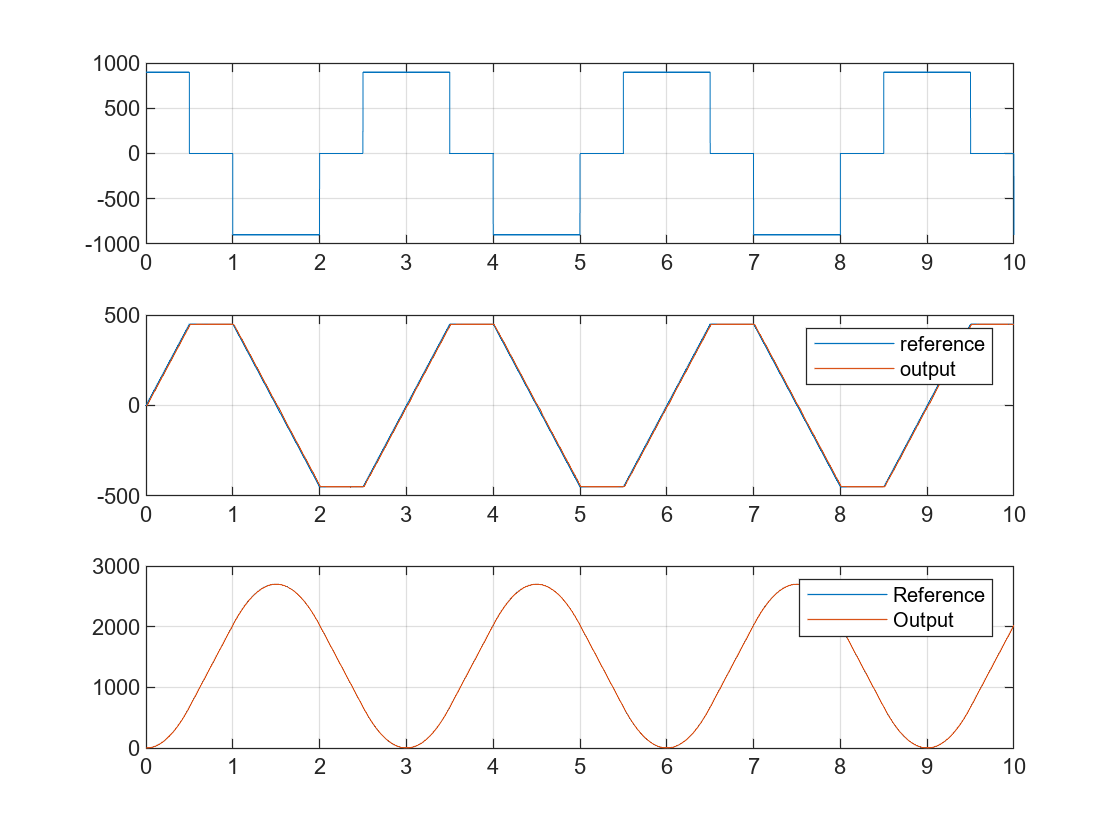

save('feedforward_sim.mat','feedforward_sim');

figure
title('Feedforward Results')
subplot(3,1,1);
plot(feedforward_sim.aref.time, feedforward_sim.aref.signals.values);
grid on;
subplot(3,1,2);
plot(feedforward_sim.wref.time, feedforward_sim.wref.signals.values);
hold on;
plot(feedforward_sim.wl_meas.time, feedforward_sim.wl_meas.signals.values);
legend('reference', 'output')
grid on;
subplot(3,1,3);
plot(feedforward_sim.thref.time, feedforward_sim.thref.signals.values);
hold on;
plot(feedforward_sim.thl_meas.time, feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Output')
grid on;

simul.FFW = 0;          % enables FFW, set 0 to disable

no_feedforward_sim = sim('lab1_feedforward','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_feedforward/Feedforward compensator/Sum1
lab1_feedforward/Feedforward compensator/Sum2
lab1_feedforward/Feedforward compensator/Sum3
lab1_feedforward/Feedforward compensator/FIX  (discontinuity)
lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
<a href="matlab:open_and_hilite_hyperlink ('lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Quantizer','error')">lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Quantizer<

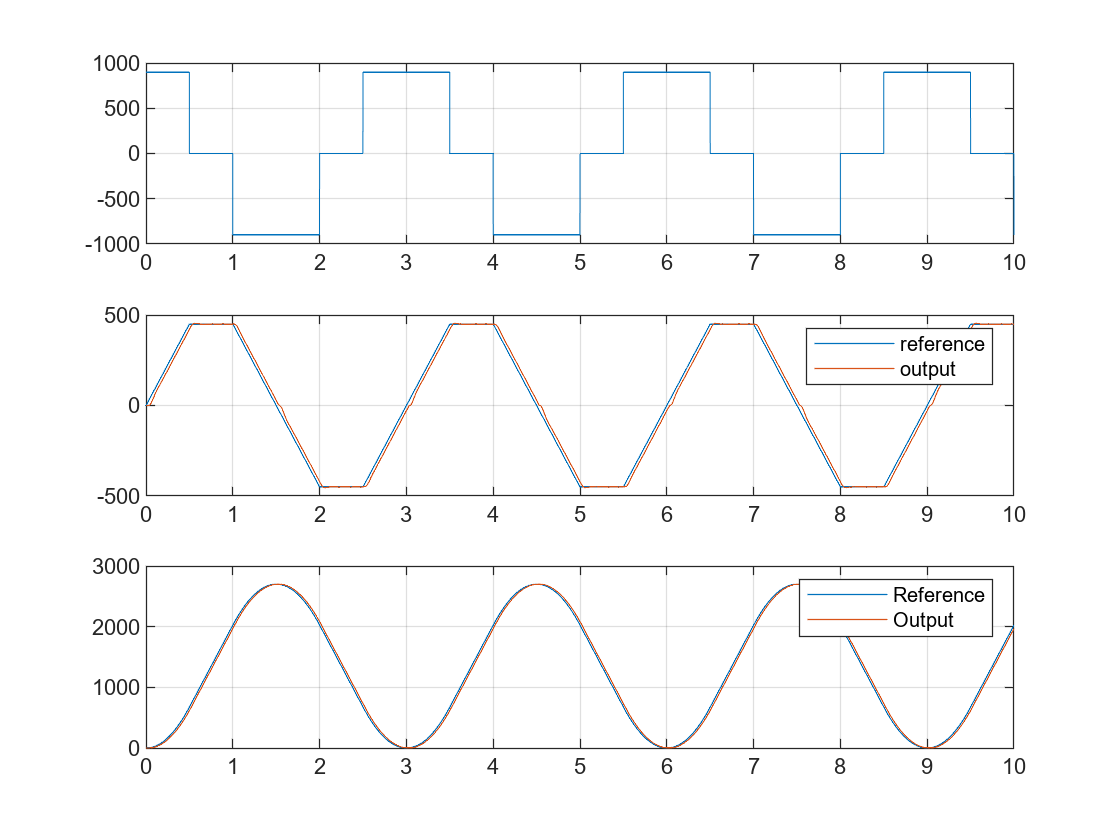

save('no_feedforward_sim.mat','no_feedforward_sim');

figure
title('Feedforward Results')
subplot(3,1,1);
plot(no_feedforward_sim.aref.time, no_feedforward_sim.aref.signals.values);
grid on;
subplot(3,1,2);
plot(no_feedforward_sim.wref.time, no_feedforward_sim.wref.signals.values);
hold on;
plot(no_feedforward_sim.wl_meas.time, no_feedforward_sim.wl_meas.signals.values);
legend('reference', 'output')
grid on;
subplot(3,1,3);
plot(no_feedforward_sim.thref.time, no_feedforward_sim.thref.signals.values);
hold on;
plot(no_feedforward_sim.thl_meas.time, no_feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Output')
grid on;

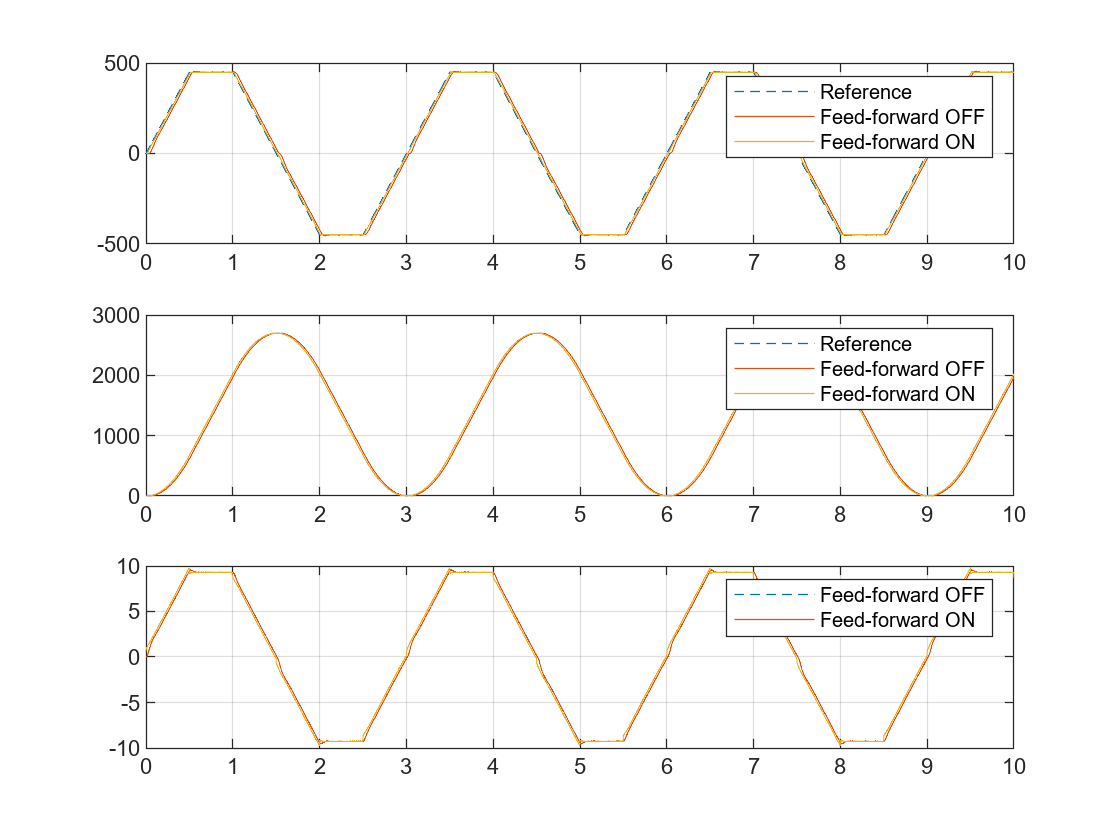

figure
title('Feedforward Results Comparison')
subplot(3,1,1);
plot(no_feedforward_sim.wref.time, no_feedforward_sim.wref.signals.values,'--');
hold on;
plot(no_feedforward_sim.wl_meas.time, no_feedforward_sim.wl_meas.signals.values);
plot(feedforward_sim.wl_meas.time, feedforward_sim.wl_meas.signals.values);
legend('Reference', 'Feed-forward OFF','Feed-forward ON')
grid on;
subplot(3,1,2);
plot(no_feedforward_sim.thref.time, no_feedforward_sim.thref.signals.values,'--');
hold on;
plot(no_feedforward_sim.thl_meas.time, no_feedforward_sim.thl_meas.signals.values);
plot(feedforward_sim.thl_meas.time, feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Feed-forward OFF','Feed-forward ON')
grid on;
subplot(3,1,3);
hold on;
plot(no_feedforward_sim.u.time, no_feedforward_sim.u.signals.values);
plot(feedforward_sim.u.time, feedforward_sim.u.signals.values);
legend('Feed-forward OFF','Feed-forward ON')
grid on;

## STATE SPACE

### **[3.2] Nominal Traking design **

Consider the problem of asymptotically tracking a step reference input $r\left(t\right)=r_{\infty } \delta_{-1} \left(t\right)$ in the ideal situation of perfect knowledge of the plant dynamics and lack of any external disturbance (nominal tracking problem). The perfect steady state tracking condition ${y_{\infty } =r_{\infty } }$ imposes that $x_{\infty }$ and $u_{\infty }$ satisfy the conditions


$$\left\lbrack \begin{array}{cc}
A & B\\
C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
N_x \\
N_u 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


where $u=-K\;x+\left(N_u +{K\;N}_x \right)r_{\infty }$ and $K$is a state feedback gain that asymptotically stabilises the closed–loop system.

For the simulations, consider either an “ideal” situation with no static friction, or a “real” situation with a static friction torque as estimated in the previous laboratory activity. Perform the tests with three different position set–points, e.g. **40°**, **70°** and **120°**.

simul.stepdeg = 40;
nominal_track_40 = sim('lab1_ss','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_ss/State-space Controller/State feedback gain
lab1_ss/State-space Controller/Sum1
lab1_ss/State-space Controller/Saturation (discontinuity)
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)


save('nominal_track_40.mat','nominal_track_40');

simul.stepdeg = 70;
nominal_track_70 = sim('lab1_ss','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_ss/State-space Controller/State feedback gain
lab1_ss/State-space Controller/Sum1
lab1_ss/State-space Controller/Saturation (discontinuity)
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)


save('nominal_track_70.mat','nominal_track_70');

simul.stepdeg = 120;
nominal_track_120 = sim('lab1_ss','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_ss/State-space Controller/State feedback gain
lab1_ss/State-space Controller/Sum1
lab1_ss/State-space Controller/Saturation (discontinuity)
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_ss/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)


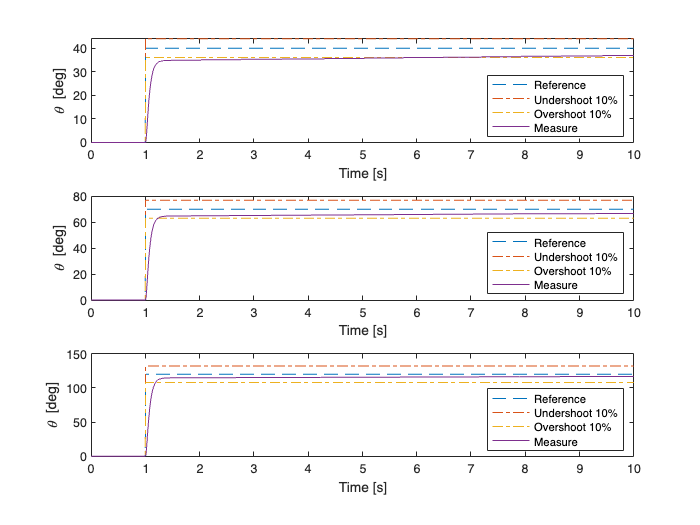

save('nominal_track_120.mat','nominal_track_120');

figure
subplot(3,1,1)
plot(nominal_track_40.thref.time, nominal_track_40.thref.signals.values,'--');
hold on;
plot(nominal_track_40.thref.time, nominal_track_40.thref.signals.values*1.10,'-.');
plot(nominal_track_40.thref.time, nominal_track_40.thref.signals.values*0.9,'-.');
plot(nominal_track_40.thl_meas.time, nominal_track_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')

subplot(3,1,2)
plot(nominal_track_70.thref.time, nominal_track_70.thref.signals.values,'--');
hold on;
plot(nominal_track_70.thref.time, nominal_track_70.thref.signals.values*1.10,'-.');
plot(nominal_track_70.thref.time, nominal_track_70.thref.signals.values*0.9,'-.');
plot(nominal_track_70.thl_meas.time, nominal_track_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')

subplot(3,1,3)
plot(nominal_track_120.thref.time, nominal_track_120.thref.signals.values,'--');
hold on;
plot(nominal_track_120.thref.time, nominal_track_120.thref.signals.values*1.10,'-.');
plot(nominal_track_120.thref.time, nominal_track_120.thref.signals.values*0.9,'-.');
plot(nominal_track_120.thl_meas.time, nominal_track_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')

### **[3.2] Robust Traking **

**of constant postion set-point and rejection of constant load disturbances**

In this case we consider the augmented state system


$$\left\lbrack \begin{array}{c}
\dot{x_I } \left(t\right)\\
\dot{x} \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & C\\
0 & A
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_I \left(t\right)\\
x\left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
B
\end{array}\right\rbrack u-\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$$


If the pair (A, B) is reachable and the open loop transfer function H(s) = C(sI − A)−1B has no zeros at s = 0, then Σe is reachable and therefore the eigenvalues of the closed–loop system, namely the eigenvalues of


$$A_{\mathrm{cl}} =\left\lbrack \begin{array}{cc}
0 & C\\
-B\;K_I  & A-B\;K
\end{array}\right\rbrack$$


can be placed at arbitrary position by properly selecting the feedback gain matrix Ke.

simul.stepdeg = 40;
robust_track_40 = sim('lab1_ss_robust','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_ss_robust/State-space Controller/State feedback gain
lab1_ss_robust/State-space Controller/Sum1
lab1_ss_robust/State-space Controller/Saturation (discontinuity)
lab1_ss_robust/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_ss_robust/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_s

save('robust_track_40.mat','robust_track_40');

simul.stepdeg = 70;
robust_track_70 = sim('lab1_ss_robust','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_ss_robust/State-space Controller/State feedback gain
lab1_ss_robust/State-space Controller/Sum1
lab1_ss_robust/State-space Controller/Saturation (discontinuity)
lab1_ss_robust/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_ss_robust/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_s

save('robust_track_70.mat_robust','robust_track_70');

simul.stepdeg = 120;
robust_track_120 = sim('lab1_ss_robust','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_ss_robust/State-space Controller/State feedback gain
lab1_ss_robust/State-space Controller/Sum1
lab1_ss_robust/State-space Controller/Saturation (discontinuity)
lab1_ss_robust/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_ss_robust/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_s

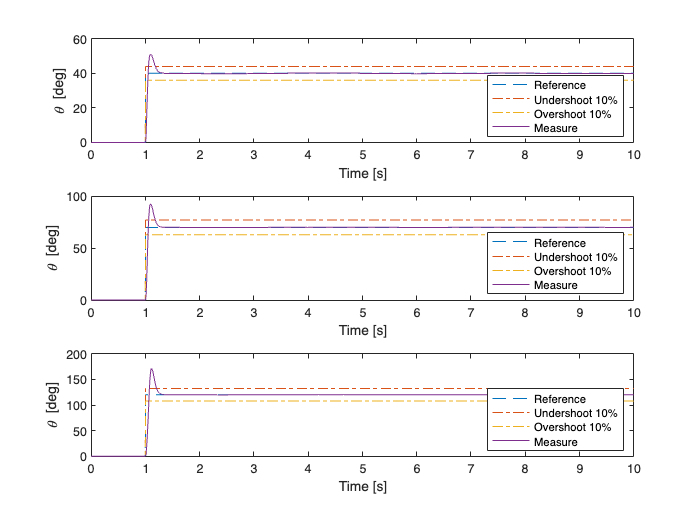

save('robust_track_120.mat','robust_track_120');

figure
subplot(3,1,1)
plot(robust_track_40.thref.time, robust_track_40.thref.signals.values,'--');
hold on;
plot(robust_track_40.thref.time, robust_track_40.thref.signals.values*1.10,'-.');
plot(robust_track_40.thref.time, robust_track_40.thref.signals.values*0.9,'-.');
plot(robust_track_40.thl_meas.time, robust_track_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')

subplot(3,1,2)
plot(robust_track_70.thref.time, robust_track_70.thref.signals.values,'--');
hold on;
plot(robust_track_70.thref.time, robust_track_70.thref.signals.values*1.10,'-.');
plot(robust_track_70.thref.time, robust_track_70.thref.signals.values*0.9,'-.');
plot(robust_track_70.thl_meas.time, robust_track_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')

subplot(3,1,3)
plot(robust_track_120.thref.time, robust_track_120.thref.signals.values,'--');

hold on;
plot(robust_track_120.thref.time, robust_track_120.thref.signals.values*1.10,'-.');
plot(robust_track_120.thref.time, robust_track_120.thref.signals.values*0.9,'-.');
plot(robust_track_120.thl_meas.time, robust_track_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')

### **[3.3] Error space**

Design a position state–space controller for the Quanser SRV–02 servomotor that guarantees the perfect steady state robust tracking of a sinusoidal position reference of a specified pe- riod Tr, and perfect rejection of constant load disturbances, using the error–space approach.

ssError.ridx = 1;        % varies from 1 to 4 to select the correct choice of the sinusoid period
ssError.amp = 40;       % Sine amplitude


error_space = sim('lab1_error_space','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_error_space/State-space Controller/Saturation (discontinuity)
lab1_error_space/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_error_space/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_error_space/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab1_error_space/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)


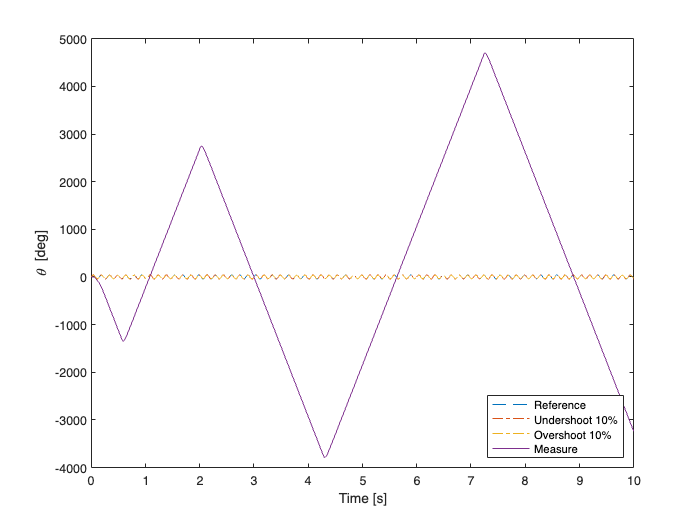

save('error_space.mat','error_space');

figure
plot(error_space.thref.time, error_space.thref.signals.values,'--');
hold on;
plot(error_space.thref.time, error_space.thref.signals.values*1.10,'-.');
plot(error_space.thref.time, error_space.thref.signals.values*0.9,'-.');
plot(error_space.thl_meas.time, error_space.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')